clear all;
close all;
clc;
% Capture the start time
startTime = datetime('now');
disp(['Start Time: ', datestr(startTime)]);

Start Time: 06-Aug-2024 12:11:14



addpath(genpath('.\tcSVD-master'));  % Ensure you have the required libraries
addpath(genpath('.\HSIdata'));
addpath(genpath('.\libSVM'));
addpath('.\functions');


file_path = '004-02reflectance.mat';

% Display information about the HDF5 file
info = h5info(file_path);
disp('Dataset keys:');

Dataset keys:


disp({info.Datasets.Name});

    {'gt'}    {'refl'}




% Replace 'refl' and 'gt' with the actual dataset names if different
hsi_data = h5read(file_path, '/refl');
gt = h5read(file_path, '/gt');

% Display the sizes of the loaded data
disp(['HSI data size: ', mat2str(size(hsi_data))]);

HSI data size: [389 345 826]


disp(['Ground truth size: ', mat2str(size(gt))]);

Ground truth size: [389 345]


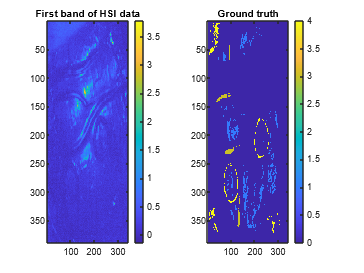


% Optionally, visualize the data
figure;
subplot(1, 2, 1);
imagesc(hsi_data(:, :, 1)); % Display the first band
title('First band of HSI data');
colorbar;

subplot(1, 2, 2);
imagesc(gt); % Display the ground truth
title('Ground truth');
colorbar;


%% Parameters (Can be changed as required)
u = 2; w = 2*u + 1; w2 = w * w;  % Research region
L = 9;  % Embedding L

%% Custom Padding Function
function padded = custom_padarray(A, padSize, method)
    [rows, cols, bands] = size(A);
    padded = zeros(rows + 2*padSize(1), cols + 2*padSize(2), bands);
    
    if strcmp(method, 'symmetric')
        % Fill the middle part of the padded array with the original data
        padded(padSize(1)+1:end-padSize(1), padSize(2)+1:end-padSize(2), :) = A;
        
        % Fill the borders with symmetric padding
        % Top border
        padded(1:padSize(1), padSize(2)+1:end-padSize(2), :) = flipud(A(1:padSize(1), :, :));
        % Bottom border
        padded(end-padSize(1)+1:end, padSize(2)+1:end-padSize(2), :) = flipud(A(end-padSize(1)+1:end, :, :));
        % Left border
        padded(padSize(1)+1:end-padSize(1), 1:padSize(2), :) = fliplr(A(:, 1:padSize(2), :));
        % Right border
        padded(padSize(1)+1:end-padSize(1), end-padSize(2)+1:end, :) = fliplr(A(:, end-padSize(2)+1:end, :));
        
        % Fill the corners
        % Top-left corner
        padded(1:padSize(1), 1:padSize(2), :) = rot90(A(1:padSize(1), 1:padSize(2), :), 2);
        % Top-right corner
        padded(1:padSize(1), end-padSize(2)+1:end, :) = rot90(A(1:padSize(1), end-padSize(2)+1:end, :), 2);
        % Bottom-left corner
        padded(end-padSize(1)+1:end, 1:padSize(2), :) = rot90(A(end-padSize(1)+1:end, 1:padSize(2), :), 2);
        % Bottom-right corner
        padded(end-padSize(1)+1:end, end-padSize(2)+1:end, :) = rot90(A(end-padSize(1)+1:end, end-padSize(2)+1:end, :), 2);
    else
        error('Only symmetric padding is implemented in this custom padding function.');
    end
end

%% Tensor SVD-like Function
function [U, S, V] = tSVD(tensor_data, rank)
    % Convert the tensor to a 2D matrix for decomposition
    [W, H, B] = size(tensor_data);
    X = reshape(tensor_data, [W*H, B]);
    
    % Perform SVD on the 2D matrix
    [U, S, V] = svd(X, 'econ');
    
    % Ensure rank does not exceed available dimensions
    rank = min(rank, size(U, 2));
    
    % Retain only the specified rank
    U = U(:, 1:rank);
    S = S(1:rank, 1:rank);
    V = V(:, 1:rank);
end

%% Main Processing
padded_img = custom_padarray(hsi_data, [u, u], 'symmetric');  % Use custom padding function
[W, H, B] = size(hsi_data);

% Initialize variables to store results
Id = zeros(L, W * H, 'single');
Fea_cube = zeros(L, B, 'single'); % Process one pixel at a time
img_tube = zeros(W, H, 'single'); % Initialize result matrix

% Process the image in chunks
k = 0;
for i = 1:W
    for j = 1:H
        i1 = i + u; 
        j1 = j + u;
        k = k + 1;
        
        % Ensure indices are within bounds
        if i1 - u > 0 && i1 + u <= size(padded_img, 1) && j1 - u > 0 && j1 + u <= size(padded_img, 2)
            testcube = padded_img(i1 - u:i1 + u, j1 - u:j1 + u, :);
            m = reshape(testcube, [w2, B]);
            
            % NED
            center = m((w2 + 1)/2, :); 
            NED = zeros(1, w2);
            for ii = 1:w2
                NED(:, ii) = sqrt(sum((m(ii, :) / norm(m(ii, :)) - center / norm(center)).^2)); % NED
            end
            [~, ind] = sort(NED); 
            index = ind(1:L);
            
            % Ensure index values are valid
            if all(index <= size(m, 1))
                Id(:, k) = index;
                Fea_cube = m(index, :); % Only keep features for current pixel

                % Tensor SVD-like processing
                [U, S, V] = tSVD(Fea_cube, 1);
                % Reshape S and V to match Fea_cube
                G = U * S * V'; % Reconstruct the tensor
                G = reshape(G, size(Fea_cube));
                N = G - Fea_cube; % Compute the difference
                normx = norm(N(:));
                img_tube(i, j) = normx; % Store the result in img_tube
            end
        end
    end
end

save('tubeSSA.mat', 'img_tube');

load('tubeSSA.mat');
tubeSSA = img_tube;

% For classification
% Split dataset into training and testing sets
rng(1); % For reproducibility
num_classes = max(gt(:)); % Assuming ground truth contains class labels
per_class_samples = histcounts(gt(:), 1:num_classes+1); % Number of samples per class

% Ensure there are enough samples
num_train_per_class = 30; % Increase training samples per class

train_indices = [];
test_indices = [];
train_labels = [];
test_labels = [];

for class = 1:num_classes
    class_indices = find(gt == class);
    num_class_samples = length(class_indices);
    
    if num_class_samples >= 2 * num_train_per_class
        class_indices = class_indices(randperm(num_class_samples)); % Shuffle indices
        train_indices = [train_indices; class_indices(1:num_train_per_class)];
        test_indices = [test_indices; class_indices(num_train_per_class+1:2*num_train_per_class)];
        train_labels = [train_labels; class * ones(num_train_per_class, 1)];
        test_labels = [test_labels; class * ones(num_train_per_class, 1)];
    elseif num_class_samples > 1
        % Use all samples for training and testing if not enough samples
        split_point = floor(num_class_samples / 2);
        class_indices = class_indices(randperm(num_class_samples)); % Shuffle indices
        train_indices = [train_indices; class_indices(1:split_point)];
        test_indices = [test_indices; class_indices(split_point+1:end)];
        train_labels = [train_labels; class * ones(split_point, 1)];
        test_labels = [test_labels; class * ones(num_class_samples - split_point, 1)];
    else
        warning(['Not enough samples for class ', num2str(class), '. Skipping class.']);
    end
end


% Extract features for training and testing
train_features = tubeSSA(train_indices);
test_features = tubeSSA(test_indices);

% Normalize the features
train_features = (train_features - mean(train_features)) / std(train_features);
test_features = (test_features - mean(test_features)) / std(test_features);

% Train SVM model using fitcecoc for multiclass
model = fitcecoc(train_features, train_labels, 'Coding', 'onevsall', 'Learners', 'svm');

% Predict the labels
pred_labels = predict(model, test_features);

% Calculate accuracy
OA = sum(pred_labels == test_labels) / length(test_labels);
disp(['Overall Accuracy: ', num2str(OA * 100), '%']);

Overall Accuracy: 61.1111%



% Calculate average accuracy per class
unique_classes = unique(test_labels);
class_accuracies = zeros(length(unique_classes), 1);

for i = 1:length(unique_classes)
    class = unique_classes(i);
    class_accuracies(i) = sum(pred_labels(test_labels == class) == class) / sum(test_labels == class);
end

AA = mean(class_accuracies);
disp(['Average Accuracy: ', num2str(AA * 100), '%']);

Average Accuracy: 61.1111%



% Calculate kappa coefficient
confusionMatrix = confusionmat(test_labels, pred_labels);
N = sum(confusionMatrix(:));
po = sum(diag(confusionMatrix)) / N;
pe = sum(sum(confusionMatrix, 1) .* sum(confusionMatrix, 2)) / N^2;
kappa = (po - pe) / (1 - pe);
disp(['Kappa Coefficient: ', num2str(kappa * 100), '%']);

Kappa Coefficient: 48.3607%


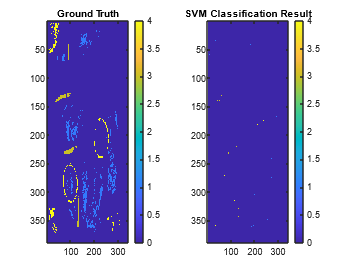


% Visualization (Optional)
figure;
subplot(1, 2, 1);
imagesc(gt); % Display the ground truth
title('Ground Truth');
colorbar;

subplot(1, 2, 2);
classified_image = zeros(W, H);
classified_image(train_indices) = train_labels;
classified_image(test_indices) = pred_labels;
imagesc(classified_image); % Display the SVM classification result
title('SVM Classification Result');
colorbar;

% Capture the end time
endTime = datetime('now');
disp(['End Time: ', datestr(endTime)]);

End Time: 06-Aug-2024 12:13:21



% Calculate execution time
executionTime = endTime - startTime;

% Convert execution time to minutes and seconds
totalSeconds = seconds(executionTime);
minutesPart = floor(totalSeconds / 60);
secondsPart = mod(totalSeconds, 60);

% Display execution time in minutes and seconds
disp(['Execution Time: ', num2str(minutesPart), ' minutes and ', num2str(secondsPart), ' seconds.']);

Execution Time: 2 minutes and 7.1462 seconds.
